tracks_matrix = h5read('xz86_3Chamber.h5','/tracks');
% frames x nodes x 2 x tracks

sum(isnan(squeeze(tracks_matrix(:,2,1))))

ans =     49


% reshape tracks into frames x (nodesx2)
tracks_matrix_linear = reshape(tracks_matrix,size(tracks_matrix,1),[]);
% fill missing
tracks_matrix_linear = fillmissing(tracks_matrix_linear,'linear');

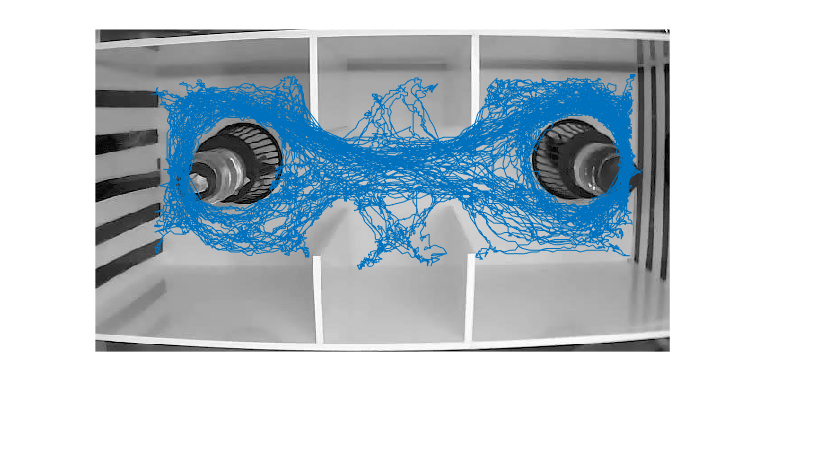

arena = imread('example_frame3.jpg');
f = figure;
a = axes('NextPlot',"add");
imshow(arena,'Parent',a);
% plot(a,tracks_matrix_linear(1:100,1),tracks_matrix_linear(1:100,3),'bo'); % nose
% plot(a,tracks_matrix_linear(1:100,2),tracks_matrix_linear(1:100,4),'ro'); % butt
tracks_center = [1/2*(tracks_matrix_linear(:,1)+tracks_matrix_linear(:,2)),1/2*(tracks_matrix_linear(:,3)+tracks_matrix_linear(:,4))];
plot(a,tracks_center(:,1),tracks_center(:,2));

% x<280, chamber 1(left); x>397, chamber 2(right)
total_length = size(tracks_matrix_linear,1);
time_spent_left = sum(tracks_matrix_linear(:,1)<=280)/total_length

time_spent_left =          0.392539356605065


time_spent_right = sum(tracks_matrix_linear(:,1)>=397)/total_length

time_spent_right =          0.481709635713742


sfi = abs((time_spent_right-time_spent_left)/(time_spent_right+time_spent_left))

sfi =          0.101996433386978


load('E:\MiniscopeData(processed)\NewCage_free_dual\3Chamber\2021_08_24\XZ86\17_37_57\Miniscope2\processed\ms.mat');
neuron = ms.FiltTraces(:,ms.cell_label);
t_behav = csvread('E:\MiniscopeData(processed)\NewCage_free_dual\3Chamber\2021_08_24\XZ86\17_37_57\BehavCam_0\timeStamps.csv',1);
t_mini = csvread('E:\MiniscopeData(processed)\NewCage_free_dual\3Chamber\2021_08_24\XZ86\17_37_57\Miniscope2\timeStamps.csv',1);
[~, B2M] = TStampAlign(t_mini(:,2),t_behav(:,2));

% find frame 319 in temporal mapping
behav_start = find(B2M>=319,1); % this is the start frame to truncate miniscope
neuron_truncate = neuron(behav_start:end,:);
track_center_mapped = tracks_center(B2M(behav_start:end)-318,:);
% top left 75,46; bottom left 75,260; top right 600,46; bottom right 600,260 

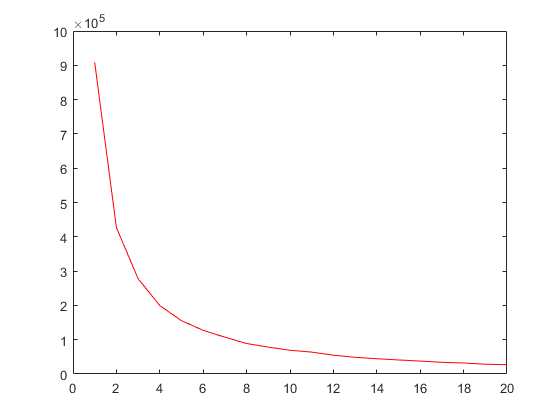

% cluster neurons by their activity
mean_dist_to_c1 = [];
neuron_truncate_zscore = zscore(neuron_truncate);
for kn = 1:20
    [idx, centro, sumd] = kmeans(transpose(neuron_truncate_zscore), kn);
    mean_dist_to_c1 = [mean_dist_to_c1, mean(sumd)];
end

figure,plot(1:20, mean_dist_to_c1,'r');

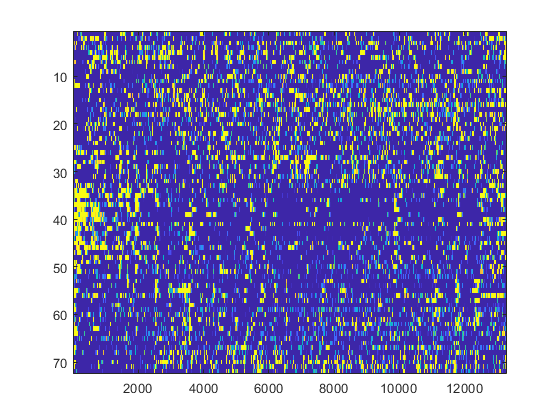

kn=7; % specify number of clusters
rng(42); % set random seed
idx1 = kmeans(neuron_truncate_zscore', kn);
[~,c_order1] = sort(idx1);
figure, imagesc(transpose(neuron_truncate_zscore(:,c_order1)), [0,1]);

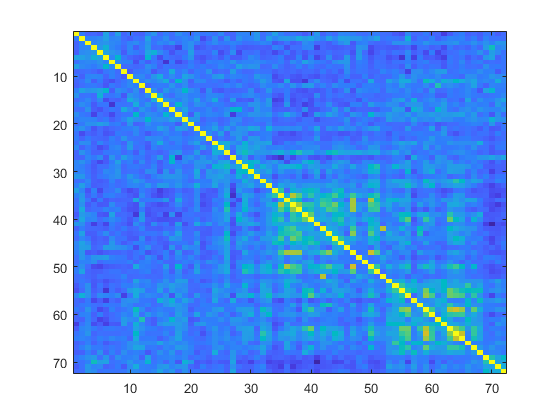

figure, imagesc(corr(neuron_truncate_zscore(:,c_order1)));

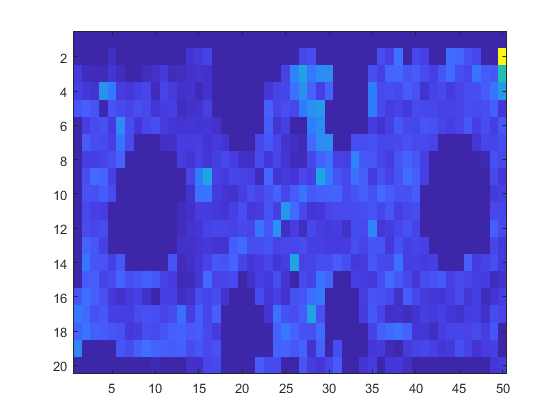

% divide into 20x50 grid
xgrid = linspace(75,600,50);
ygrid = linspace(46,260,20);
grid_count = zeros(20,50);
grid_neuron = zeros(20,50);
avg_trace = mean(zscore(neuron_truncate(:,find(idx1==4))),2);
for i = 1:size(track_center_mapped)
    current_x = track_center_mapped(i,1);
    current_y = track_center_mapped(i,2);
    xidx = find(xgrid>=current_x,1);
    yidx = find(ygrid>=current_y,1);
    grid_neuron(yidx,xidx) = grid_neuron(yidx,xidx) + avg_trace(i);
    grid_count(yidx,xidx) = grid_count(yidx,xidx) + 1;
end
figure,
imagesc(grid_neuron./grid_count)

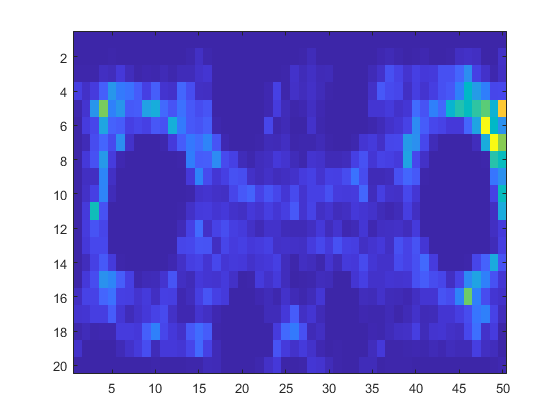

figure,
imagesc(grid_count)